# some numbers.

all times are in [ms]


dt  = 2;
tmax = 1000;
tmin = -200;
fs = 1/dt;
len_sample = floor((tmax-tmin)*fs);
t = linspace(tmin, tmax, len_sample);

noise.tscales = [150 250];
noise.delta_tscales = [300 400];
noise.amplitude = [0.5 1];
noise.jitters = [0 20:20:300] ;
noise.jitter = 0;
noise.randn = 0.1;

jitters = noise.jitters;
num_trails = 100;
freqs = logspace(log10(2), log10(60), 30);


%% generating erps data
erps = zeros(length(jitters), length(t));
trials = zeros(length(jitters), num_trails, length(t));
sub_trials = trials ;
for ii = 1:length(jitters)
    noise.jitter = noise.jitters(ii) * fs;
    trials(ii,:,:) = DeltamatWithNoise(t, num_trails, noise);
    erps(ii,:) = mean(trials(ii,:,:));
    sub_trials(ii,:,:) = bsxfun(@minus, squeeze(trials(ii,:,:)), erps(ii,:));
end

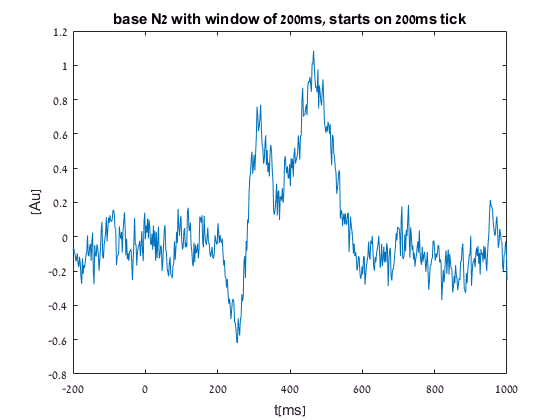


%% plot graph of each ERP with all trials
baseN2 = squeeze(trials(1,8,:))';
figure;
plot(t, baseN2 )
xlabel t[ms]
ylabel [Au]
title 'base N2 with window of 200ms, starts on 200ms tick';

## The spectrum of the original basic raw data

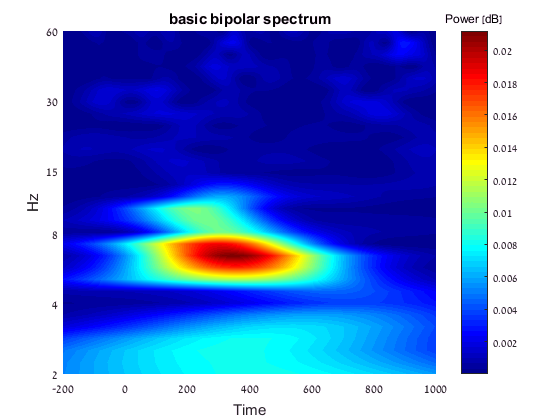

[p,pha] = getPowerSpectra(baseN2,dt, freqs);
helperCWTTimeFreqPlot(p, t, freqs, 'surf', 'basic bipolar spectrum')

## plot graph of each ERP with its subtracted trials

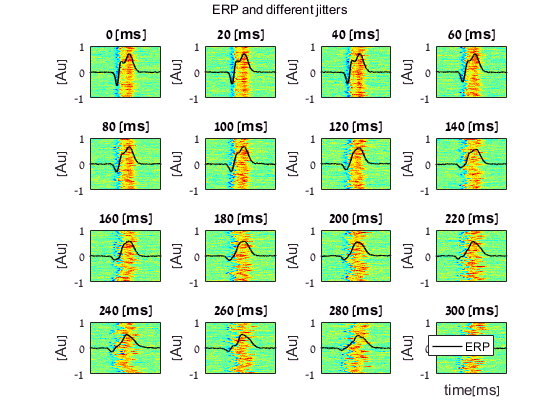

figure;
for ii = 1:length(jitters)
    % plotting all erps
    subplot(ceil(length(jitters)/4),4,ii);
    %     figure
    
    imagesc(t, [-1, 1], squeeze(trials(ii,:,:)));
    hold on
    plot(t, erps(ii,:), 'linewidth',1,'color','k');
%     plot(t, baseN2 , 'r--', 'linewidth',1)
    
    axis xy
    caxis([min(sub_trials(:)), max(sub_trials(:))]);
    set(gca,'XTick',[]);
    ylabel [Au]
    colormap jet
    title(sprintf('%d [ms]', jitters(ii)));
    hold off
end
legend({'ERP'})
xlabel time[ms]
add_subplot_title('ERP and different jitters')
set(gca,'xtickMode', 'auto')

## spectral analysis

calculate spectrum

originals_freq_power = zeros([length(jitters) length(freqs) length(t)]);
subtrials_freq_power = originals_freq_power;
total_phase = zeros([size(originals_freq_power), num_trails]);

erps_freq_power = getPowerSpectra(erps,dt, freqs); %freq-time(-channel)
if(ndims(erps_freq_power))==2
    %for ploting competability
    erps_freq_power = reshape(erps_freq_power,[1 size(erps_freq_power)]);
else
    erps_freq_power = shiftdim(erps_freq_power,2); %channel-freq-time
end

for ii = 1:length(jitters)
    [amp,ph] = getPowerSpectra(squeeze(trials(ii,:,:)),dt,freqs);
    originals_freq_power(ii,:,:) = sum(amp,3);
    total_phase(ii,:,:,:) = ph;
    
    subtrials_freq_power(ii,:,:) = sum(getPowerSpectra(squeeze(sub_trials(ii,:,:)),dt,freqs),3);
end

originals_freq_power = originals_freq_power / num_trails;
subtrials_freq_power = subtrials_freq_power / num_trails;
diff_original_subtracted_trials = originals_freq_power - subtrials_freq_power;



## phase

show table of phases for each jitter

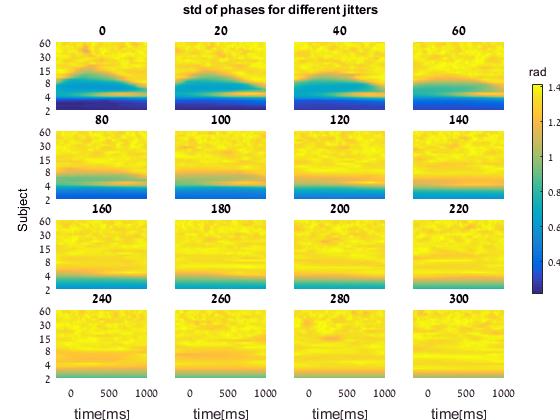

figure;
show_powers_tight(t,freqs, shiftdim(circ_std(total_phase,[],[],4),1), 4, 'std of phases for different jitters', 'rad',[], jitters)

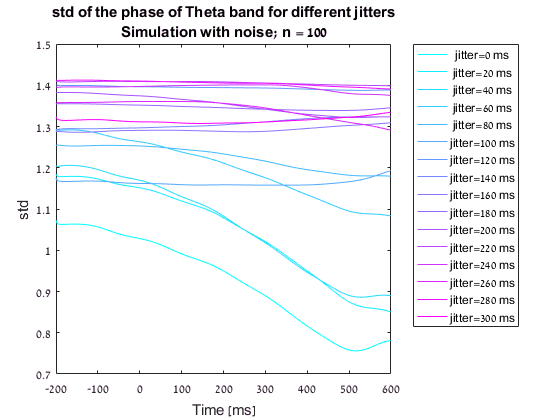

phase_hilbert = get_hilbert_phase(shiftdim(trials,2), 6, 8, dt*1000);
phase_stds = circ_std(phase_hilbert,[],[],3);
phase_mean = circ_mean(phase_hilbert,[],3);
figure;
h = plot(t(t<600),phase_stds(t<600,:));
legend(cellstr(num2str(jitters', 'jitter=%d ms')), 'Location', 'bestoutside')
set(h, {'color'}, num2cell(cool(length(h)),2));
xlabel 'Time [ms]'
ylabel 'std'
title({'std of the phase of Theta band for different jitters','Simulation with noise; n = 100'})

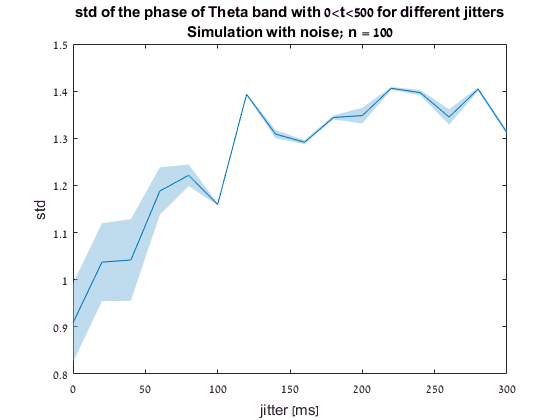

% set(gca, 'ColorOrder', [0.5 0.5 0.5; 1 0 0], 'NextPlot', 'replacechildren');

figure;
varplot(jitters,phase_stds(0<t & t<500,:)','std');
% legend(cellstr(num2str(t(1:100:400)', 'times=%.3g [ms]')))
% set(h, {'color'}, num2cell(winter(length(h)),2));
xlabel 'jitter [ms]'
ylabel 'std'
title({'std of the phase of Theta band with 0<t<500 for different jitters','Simulation with noise; n = 100'})

## power images for each jitter

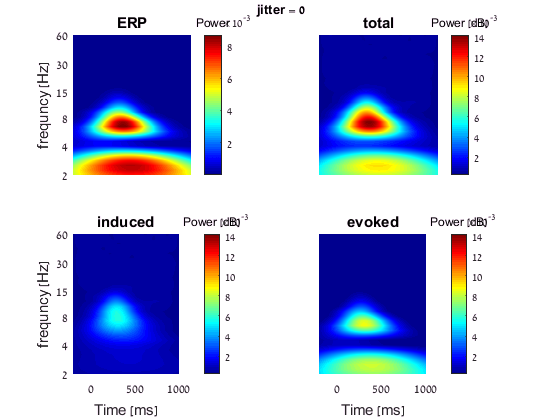

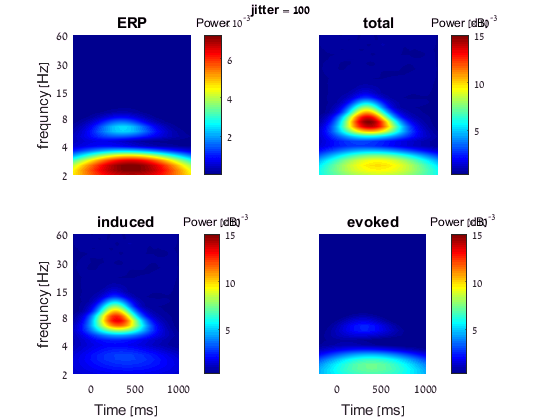

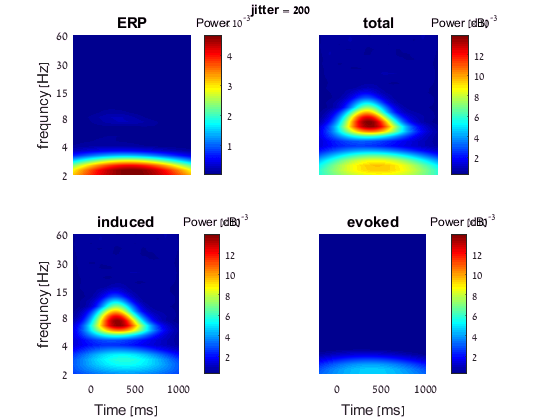

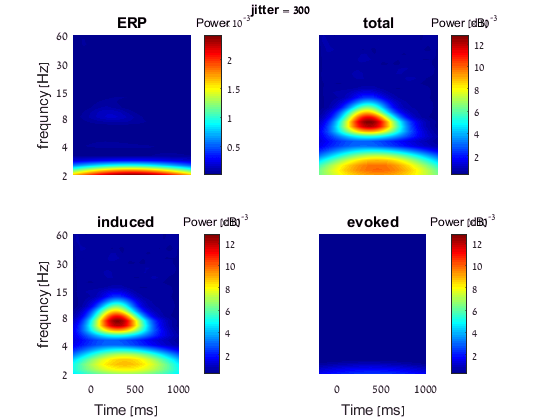



PlotType = 'contourf';
for ii = 1:5:length(jitters)
    % ii=4;
    h = figure;
    show4images(t,freqs, ...
    squeeze(erps_freq_power(ii,:,:)), ...
    squeeze(originals_freq_power(ii,:,:)),  ...
    squeeze(subtrials_freq_power(ii,:,:)), ...
    squeeze(diff_original_subtracted_trials(ii,:,:)), ...
    ['jitter = ' num2str(jitters(ii))],...
    'surf');
    
end

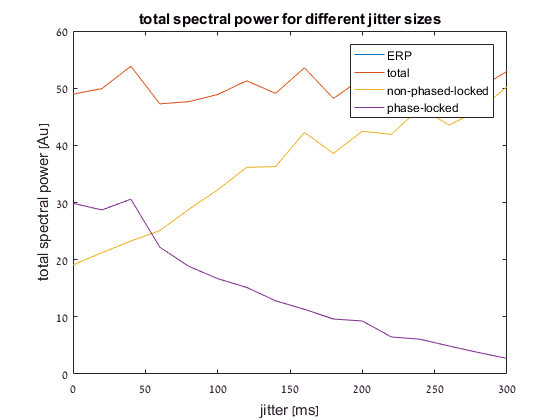

%% compare jitter size to sum of spectral information
figure
tot_freq_sum = @(X) sum(sum(X,3),2);
tot_erp = tot_freq_sum(erps_freq_power);
tot_orig = tot_freq_sum(originals_freq_power);
tot_sub = tot_freq_sum(subtrials_freq_power);
tot_diff = tot_freq_sum(diff_original_subtracted_trials);

plot(jitters, [tot_erp, tot_orig, tot_sub, tot_diff]');
title 'total spectral power for different jitter sizes'
xlabel 'jitter [ms]'
ylabel 'total spectral power [Au]'
legend({'ERP', 'total', 'non-phased-locked', 'phase-locked'})

function add_subplot_title(title)
ha = axes('Position',[0 0 1 1],'Xlim',[0 1],'Ylim',[0 1],'Box','off','Visible','off','Units','normalized', 'clipping' , 'off');
text(0.5, 1,title,'HorizontalAlignment' ,'center','VerticalAlignment', 'top');
end


function show_time_freq(amp,time,freq, title_str)
        contourf(time,freq,amp);    
        
        grid on; colormap(parula(128)); 
    title(title_str)
    xlabel('time [ms]'); ylabel('freq [Hz]');
    set(gca,'yscale','log')
%     set(gca,'YLim',[0 4])
    set(gca,'YTick',round(logspace(log10(min(freq)), log10(max(freq)), 6))) 
end